**Scratch Assay Migration Analysis Program**

Copyright © 2023 Elizabeth Bowen, UCLA

Notes: Selecting parameters will automatically run each section, but the Run button @ bottom of each section can be used to run a section without changing the parameters.

**1. Blur Image & Convert to Grayscale**

Put in the file path to the folder with the image you want to use, and enter the file name into the imgTitle field, then click enter:

% Make sure that you're in the folder with the images you want to use
addpath("/Users/elizabeth 1/Desktop/Wu Lab/cell counting practice/brightfield images/Cell Assay Analysis Package"); %load in functions for this package
filePath = "/Users/elizabeth 1/Desktop/Wu Lab/cell counting practice/brightfield images";
cd (filePath);
fileList = dir(fullfile(filePath, '*.tif'));  % List all PNG files (modify the extension as needed)

% Extract the filenames from the structure
filenames = {fileList.name}

filenames = 1×3 cell array
    {'C1 0h.tif'}    {'C1 24h.tif'}    {'C1 42h.tif'}


photoNumber = length(filenames);
%allow user to use slider to iterate through images in the specified folder
%(don't have to type in image neame each time)
i =3;
imgTitle = string(filenames(i))

imgTitle = "C1 42h.tif"

img1 = imread(imgTitle); %read in image
img = rgb2gray(img1); %convert to grayscale
img_blurred = imgaussfilt(img);
intensity_threshold = true;
variance_threshold = false;  %remove regions under this level of variance (sharpness)
%threshold by removing blurry regions under otsu's threshold of brightness, then binarized through adaptive thresholding function



%determine threshold to use based on which image we're using
if intensity_threshold
  %to run adaptive thresholding, make sure to check adaptice_thresholding,
    %and uncheck manual_thresholding.
    [bw, threshold] = adaptiveThreshold(img_blurred);
%     imshow(bw)
%     threshold
    
    disp(['Selected threshold: ' num2str(threshold)])
    bw = imbinarize(img_blurred, 'adaptive', 'Sensitivity', threshold);
    adaptive_sensitivity = threshold;
    
    
    elseif variance_threshold
        % Define the window sizes for variance calculation
        windowSizes = [3, 5, 7, 9];
        
        % Initialize a mask to store the blurry regions
        blurryMask = false(size(img_blurred));
        
        % Calculate variance at different window sizes
        for i = 1:numel(windowSizes)
            windowSize = windowSizes(i);
            
            % Calculate the local variance using imfilter and imgaussfilt
                localVariance = imfilter(double(img_blurred).^2, ones(windowSize)/windowSize^2, 'replicate') - imgaussfilt(double(img_blurred), windowSize).^2;
            
            % Find the blurry regions based on variance values
            blurryRegions = localVariance <= 90;
            
            % Accumulate the blurry regions
            blurryMask = blurryMask | blurryRegions;
        end
        
        % Apply the blurry mask to the original image
        blurryImage = img_blurred;
%         aboveThresholdMask = img_blurred > graythresh(img_blurred);
%          blurryImage(blurryMask & aboveThresholdMask) = 0;  % Set to white

        blurryImage(~blurryMask) = 0; %create an image that displays original
        % grayscale values of blurry regions, and non-blurry regions set to 0 (black)

    
     

 
    figure
    imagesc(img1)
    figure
    imagesc(blurryImage), colormap gray
    blurryBinary = ~blurryImage; %Binary image where white = blurry regions
    
    brightnessThreshold = 70; % Example threshold value
    
    % Create a binary mask for regions above the brightness threshold
    aboveThresholdMask = img_blurred > brightnessThreshold;
    
    % Set the corresponding regions in 'back' to white
    blurryBinary(aboveThresholdMask) = 1;
    figure, imagesc(blurryBinary), colormap gray
    

    % Apply a threshold to separate foreground and background
    [thresholded, sensitivity] = adaptiveThreshold(img_blurred); 

    thresholded(blurryBinary) = 1;
    bw = thresholded;

end

Selected threshold: 0.55


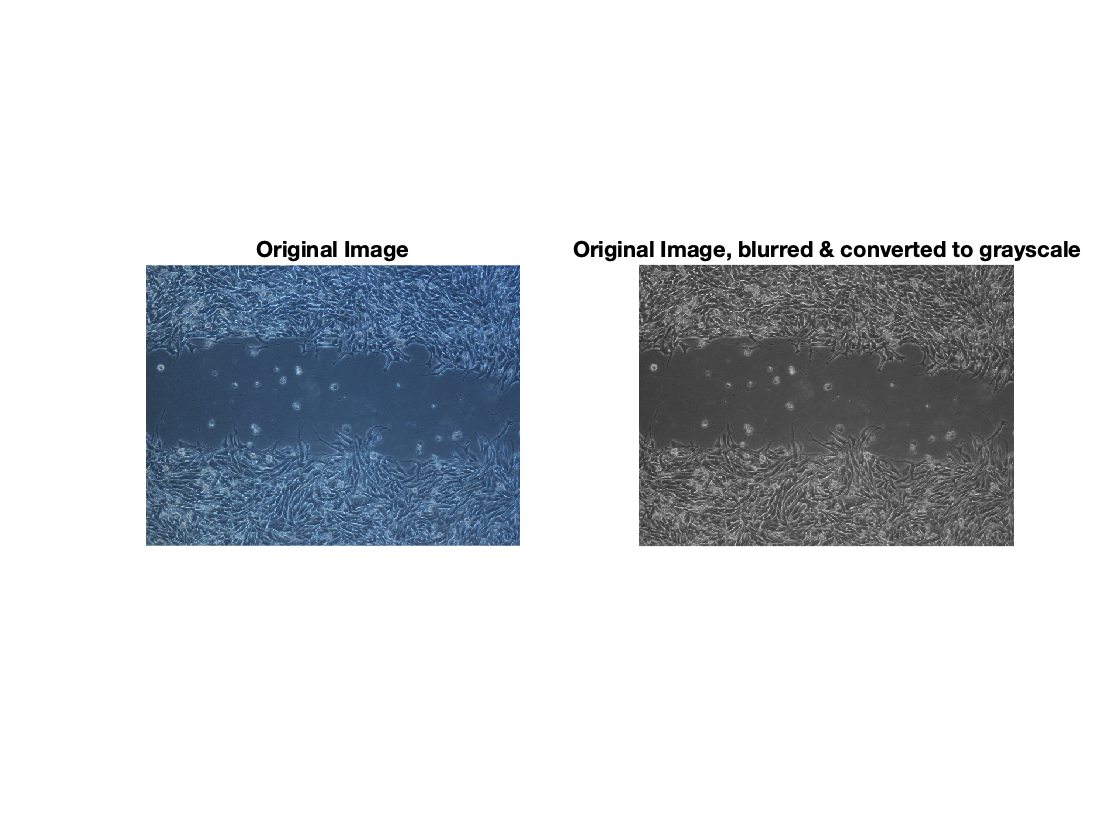


     figure
    subplot(1,2,1)
    imshow(img1); 
    title('Original Image');
    subplot(1,2,2)
    imshow(img); colormap gray
    title('Original Image, blurred & converted to grayscale');

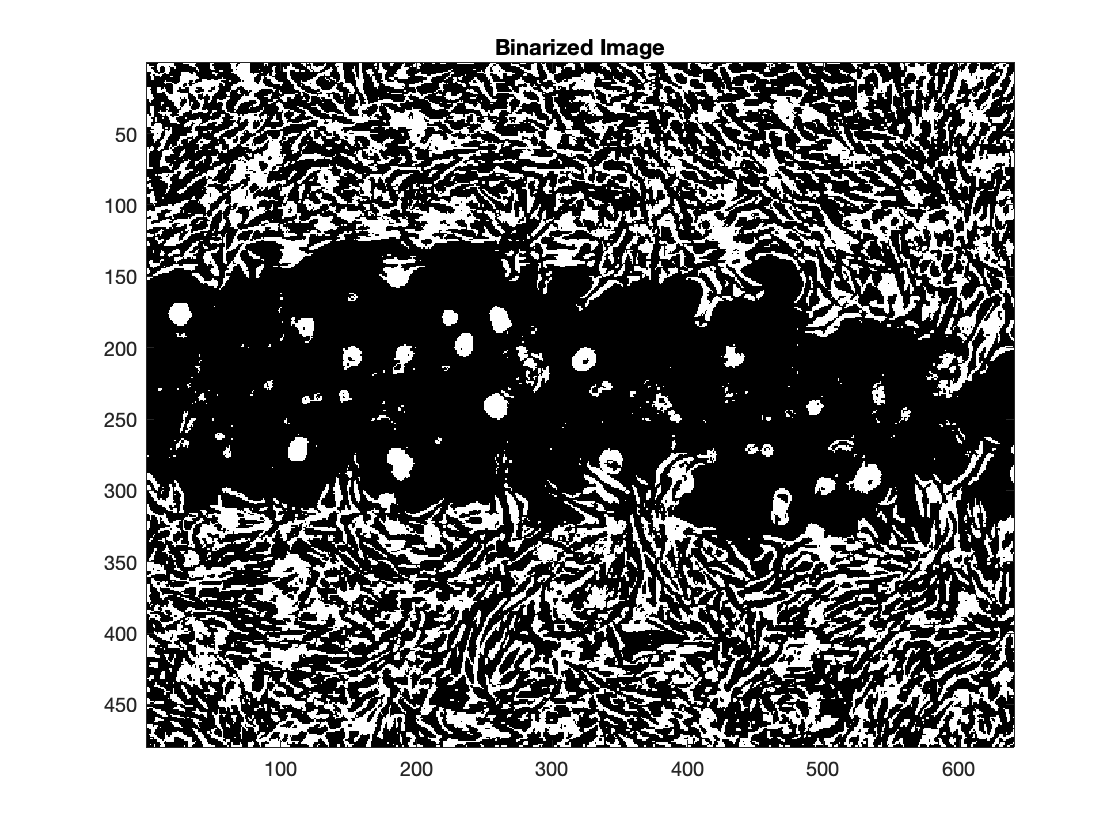

   
    
    figure
    colormap gray
    imagesc(bw),  title('Binarized Image')  

    adaptive_thresholding = true;


**2. Gap Clearing (if needed)**

skip_clearing = true; 
strel_size = 4;
    
% Create a structuring element for erosion and dilation
if ~skip_clearing
    se = strel('disk', strel_size); % Change the disk size as needed

    % Perform erosion and dilation
    eroded = imerode(bw, se);
    dilated = imdilate(bw, se);
    
    % Subtract eroded image from dilated image to get the boundaries
    boundaries = imcomplement(dilated - eroded);
    figure
    subplot(1,1,1)
    %imshow(boundaries)
    
    % Fill the holes in the boundaries under a certain size
    filled = imfill(boundaries, 'holes');
    %imshow(filled)
    back = bwareaopen(~filled,3000);
    % Threshold for brightness (adjust as needed)

    imagesc(back), colormap gray,  title('Gap Cleared') 
else
    back = bw;
    strel_size = NaN;
end



**3. segment automatically with dilation & erosion:**


%where store data from image analysis (table & montage)
tableName = "test"+'.xls'; %excel file where you want to store analysis stats
filePath = "/Users/elizabeth 1/Desktop/Wu Lab/cell counting practice/brightfield images";  %directory in which to create/look for table & to store images
cd(filePath)

minimum_strel = 2;
 
strel_range = minimum_strel:3:60;
[complement, final_strel] = gapSegmentation(back, strel_range); % assign the final image to the var complement

bool = logical
   0



%show the final image & display its strel size used 
main_strel = final_strel; % for stats table


fprintf('[Strel size = %d] compared to original:', final_strel); % label the comparison here so that we have the right value of i (inside a for loop)

[Strel size = 2] compared to original:

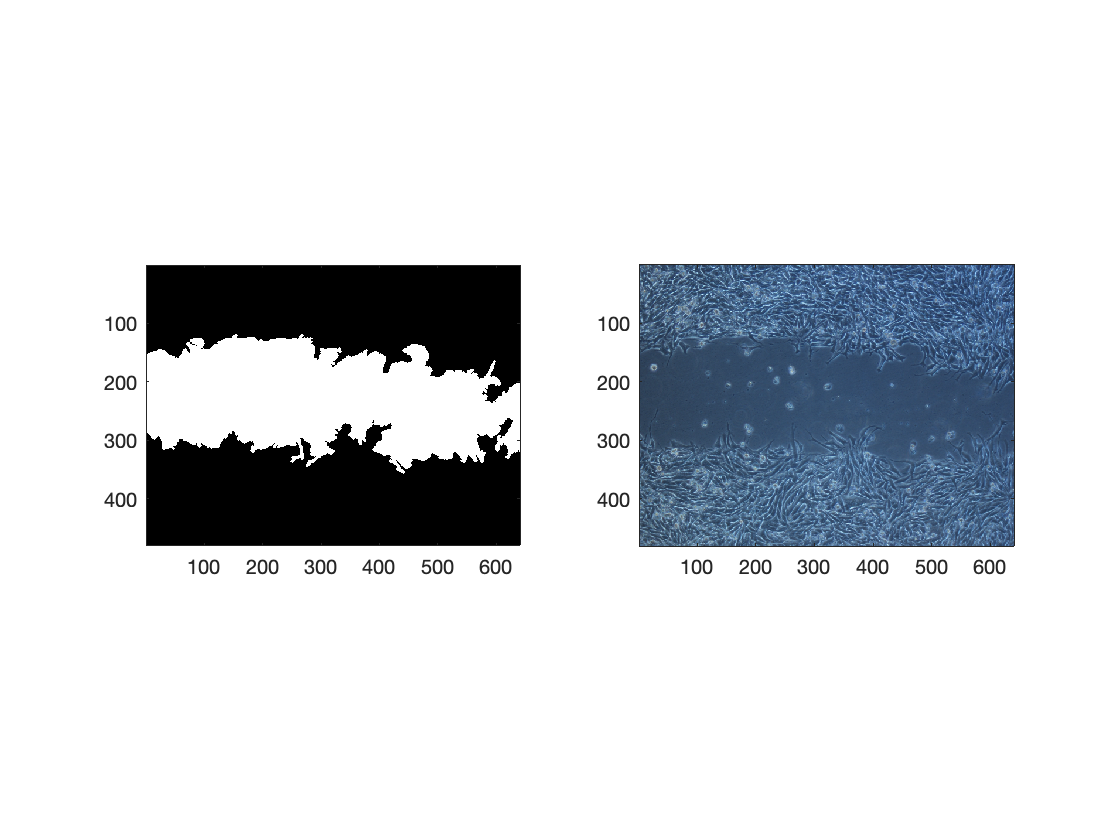

figure, colormap gray
subplot(1,2,1);
imagesc(complement), axis image, colormap gray;
subplot(1,2,2);
imagesc(img1), axis image, colormap gray;

final_image = complement;

%produce montage

C = imfuse(final_image,img1,'montage');

S = extractBefore(imgTitle, '.');
fileName = "MONTAGE " + S + '.jpg';
imwrite(C,fileName)

fprintf('Image Montage (Downloaded): [%s]', fileName)

Image Montage (Downloaded): [MONTAGE C1 42h.jpg]

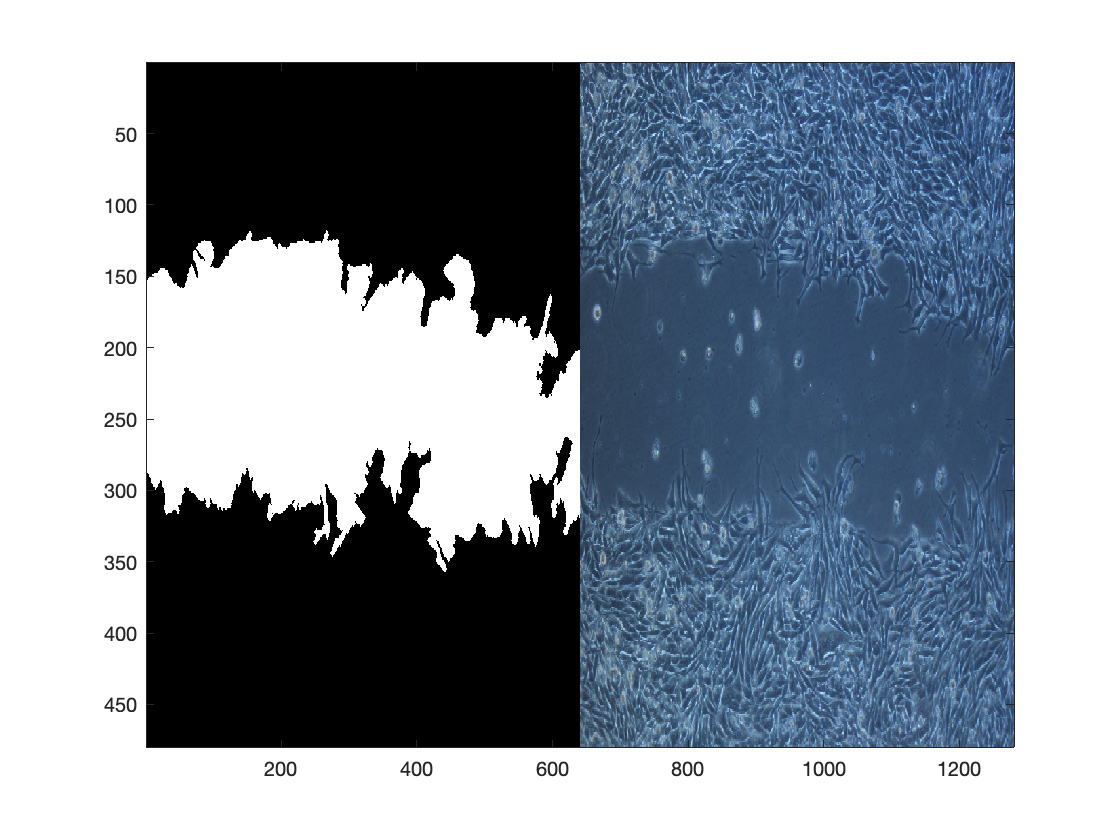

subplot(1,1,1);
imagesc(C), colormap gray


%calculate gap area
stats = regionprops(final_image, 'Area');
    allAreas = [stats.Area];
    gapArea = max(allAreas);

    clipboard('copy',gapArea)  
fprintf('Final Gap Area = %d\n', gapArea)

Final Gap Area = 101122



if ~isfile(tableName) %if the table does not already exist
    colNames = {'Photo Name', 'gap area (pixels)'};
    data = cell(1,2); % create a cell array with one row and the same number of columns as colNames
    table = [cell2table(colNames, 'VariableNames', colNames); cell2table(data, 'VariableNames', colNames)]
    writetable(table, tableName);
    existingTable = readtable(tableName);
    existingTable(1,:) = []; %remove duplicate column names row
else
    existingTable = readtable(tableName); %no need to remove duplicate col name row in this case
end

fprintf('This table is stored as %s in %s:', tableName, filePath)

This table is stored as test.xls in /Users/elizabeth 1/Desktop/Wu Lab/cell counting practice/brightfield images:


newRow = {imgTitle, gapArea}; 


data = [existingTable;newRow]; %add data from analysis
% Find the unique values in PhotoName column
[~, ia, ~] = unique(flipud(data.PhotoName),'rows', 'stable');
ia = size(data,1) - ia + 1;% Select only the rows that contain unique values. If you ran code for
% the same image >1 time, the program will save the most recent version of
analysisStats = flipud(data(ia, :))

analysisStats = 3×2 table
     PhotoName      gapArea_pixels_
    ____________    _______________

    "C1 0h.tif"       1.4604e+05   
    "C1 24h.tif"      1.1886e+05   
    "C1 42h.tif"      1.0112e+05   



writetable(analysisStats, tableName, 'WriteMode', 'overwrite'); %add data to table